load('mazeJ0916Reduced.mat')
spike_count = zeros(length(R), length(R(1).unit));
% find the spike counts within the time range
for x = 1:length(R)
    appeartime = R(x).targetAppearsTime;
    upper = appeartime + 400;
    lower = appeartime + 100;
    for y = 1: length(R(1).unit)
        spike_count(x, y) = length(find(R(x).unit(y).spikeTimes  > lower &  R(x).unit(y).spikeTimes <upper));
    end
end

conds = unique([R.conditionID]);
ave_spike = zeros(2,length(R(1).unit));
% each row for each condition
for i = 1:2
    cond = conds(i);
    indx = find([R.conditionID]==cond);
    ave_spike(i,:)= mean(spike_count(indx,:),1) * 1000/300;
end

tuned = find(abs(ave_spike(1,:)-ave_spike(2,:))>=2);

X = squeeze(spike_count(:, tuned));
y = ones(1,58);
y(1,indx) = 2;
% Build the model
svm_model = fitcnb(X, y, 'Distribution', 'kernel');

% Perform 10-fold cross-validation
cv = crossval(svm_model, 'kfold', 10);

% Calculate the percentage of trials classified correctly
accuracy = 1 - kfoldLoss(cv, 'lossfun', 'classiferror');

% Fit the logistic regression model using glmfit
y = y'-1;
[B, dev, stats] = glmfit(X, y, 'binomial');


% Perform 10-fold cross-validation
cv = cvpartition(size(X, 1), 'KFold', 10);
yhat = nan(size(y));
for j = 1:cv.NumTestSets
    train_idx = cv.training(j);
    test_idx = cv.test(j);
    Bcv = glmfit(X(train_idx,:), y(train_idx), 'binomial');
    yhat(test_idx) = glmval(Bcv, X(test_idx,:), 'logit');
end


% Calculate the percentage of trials correctly classified
pctCorrect = sum(round(yhat) == y) / numel(y) * 100;
fprintf('Logistic regression correctly classified %.2f%% of trials.\n', pctCorrect);

Logistic regression correctly classified 77.59% of trials.


Why do you think the fitting procedure produces warnings?

Because without regularization, the fitting can always be perfect as classifier can always be a number that can perfectly seperate the small amount of training set. However, this may cause the issue of overfitting. 

% First, divide the data up
cv = cvpartition(size(X,1),'HoldOut',0.3);
Xtrain = X(training(cv),:);
ytrain = y(training(cv));
Xtest = X(test(cv),:);
ytest = y(test(cv));

% Build the model with training data
[B,FitInfo] = lassoglm(Xtrain,ytrain,'binomial','CV',10, Alpha=0.1);
idxLambdaMinDeviance = FitInfo.IndexMinDeviance;
B0 = FitInfo.Intercept(idxLambdaMinDeviance);
beta_opt = [B0; B(:,idxLambdaMinDeviance)];
y_pred = glmval(beta_opt, Xtest, 'logit') > 0.5;

% Compute the percentage of trials classified correctly
accuracy = sum(y_pred == ytest) / length(ytest);
disp(['Accuracy: ' num2str(accuracy*100) '%']);

Accuracy: 76.4706%


Why does this regularization make the warnings go away?

Because L1 and L2 regularization help to address the issue of overfitting in logistic regression models with high-dimensional data. Now that with the regularization, the fitting is not always perfect anymore. 

y(y == 0) = -1;
svm_model = fitcsvm(X, y, 'KernelFunction', 'linear');

% Perform 10-fold cross-validation and assess performance
cv = crossval(svm_model, 'KFold', 10);
svm_loss = kfoldLoss(cv);
svm_accuracy = 1 - svm_loss;
fprintf('SVM accuracy: %.2f%%\n', svm_accuracy*100);

SVM accuracy: 84.48%


Why doesn’t this fit have trouble like logistic regression did?

SVM use a margin-based loss function that encourages a wider margin between the decision boundary and the training data. Therefore, this wider margin helps to prevent the model from fitting noise in the data and generalizing better to new, unseen data. However, logistic regression does not encourage that and therefore is more prone to overfitting. 

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.15517 |     0.06366 |     0.15517 |     0.15517 |       149.54 |       508.87 |


|    2 | Accept |     0.48276 |    0.045605 |     0.15517 |     0.17779 |       1.1093 |       0.5118 |
|    3 | Accept |     0.48276 |    0.050435 |     0.15517 |     0.15521 |     0.035917 |       179.03 |
|    4 | Accept |     0.48276 |    0.050268 |     0.15517 |     0.15522 |       351.23 |      0.12777 |
|    5 | Best   |     0.13793 |     0.04626 |     0.13793 |     0.13794 |       456.61 |       818.39 |
|    6 | Accept |     0.15517 |    0.045215 |     0.13793 |      0.1379 |       999.34 |       250.63 |
|    7 | Best   |    0.086207 |    0.047741 |    0.086207 |     0.10219 |       990.64 |        997.9 |
|    8 | Accept |    0.086207 |    0.046197 |    0.086207 |    0.095023 |       974.04 |       999.59 |
|    9 | Accept |    0.086207 |    0.044594 |    0.086207 |    0.091884 |       964.49 |       996.67 |
|   10 | Accept |    0.086207 |    0.048417 |    0.086207 |    0.090179 |       965.94 |       991.25 |
|   11 | Accept |     0.48276 |    0.043207 |    0.086207 |    0

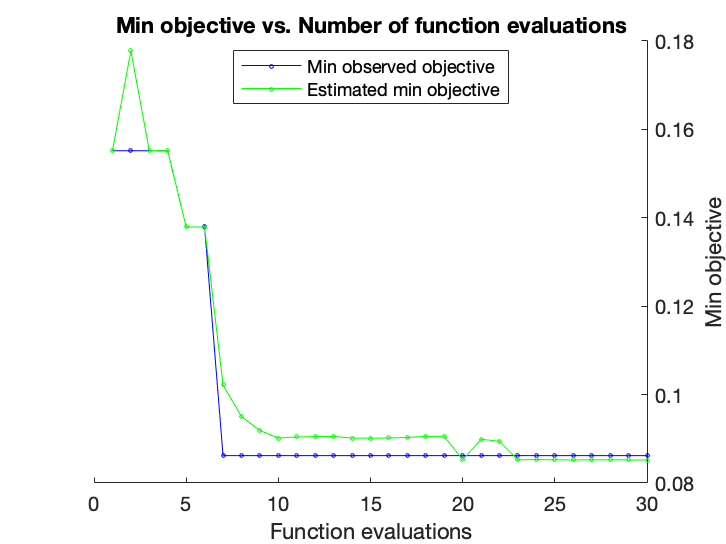

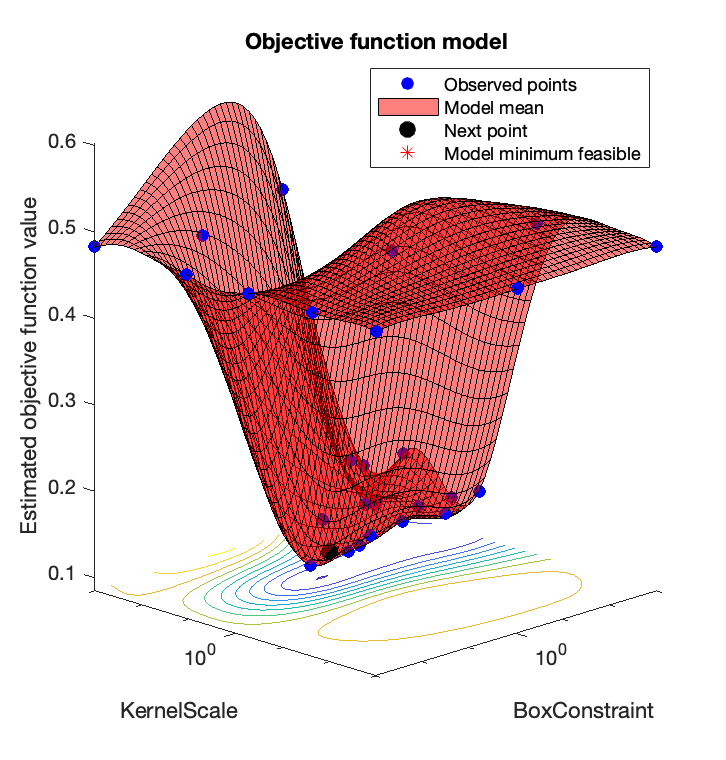


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 16.9117 seconds
Total objective function evaluation time: 1.4687

Best observed feasible point:
    BoxConstraint    KernelScale
    _____________    ___________

       990.64           997.9   

Observed objective function value = 0.086207
Estimated objective function value = 0.085201
Function evaluation time = 0.047741

Best estimated feasible point (according to models):
    BoxConstraint    KernelScale
    _____________    ___________

       990.64           997.9   

Estimated objective function value = 0.085201
Estimated function evaluation time = 0.048742



svm = fitcsvm(X, y, 'KernelFunction', 'RBF', 'OptimizeHyperparameters', 'auto');

CVSVMModel = crossval(svm); % 10 fold cross validation
classLoss = 1-kfoldLoss(CVSVMModel); % average accuracy
fprintf('SVM accuracy: %.2f%%\n', classLoss*100);

SVM accuracy: 87.93%


How does this model’s performance compare to the others? Why do you think that is?

This model performed better than other models, implying that the data might have a higher-dimension structure that can be optimized by this model. 